# **TP2 CMSI : METHODE DES DIFFERENCES FINIES**

Autre méthode de résolution de systèmes, ici résolution d'une équa diff, avec la methode des différences finies.

Il faut d'abord modéliser la pièce de métal avec les points particuliers (températures définies).

Chacune des températures (aux intersections du quadrillage) est liée par une équation linéaire à la température de ses voisins, ce qui nous donne un système d'équations linéaires de type AX = B, avec A la matrice qui représente les coefs de pondération des températures et X le vecteur solution. On a 1000 equations de type AX = B.

'Explication' d'une évolution de temperature : un point correspond à la moyenne des temperatures des voisins. Ainsi, si sa temperature est egale à la moyenne de celles des voisins, il est logique que sa temperature n'évolue pas, on se retrouve donc en situation d'équilibre. Autrement, s'il est plus chaud, respectivement plus froid, il est logique qu'il réchauffe, resp. refroidisse, ses voisins.

On suppose également, avec la condition du/dn = 0, que la temperature du point fictif normal au bord a la meme temperature que le point le plus proche (appartenant au bord).

#### Repartition fixe de la temperature

Pour visualiser la solution, nous representerons cela sous forme d'une surface avec des altitudes caractérisant les altitudes grace aux fonctions surf() et reshape(X, [50,20]).

On commence par representer la surface sous forme d'une matrice B 20x50.

B = zeros(20,50);
lines = size(B,1); % utile pour points part.
columns = size(B,2); % utile pour points part.

Maintenant, on va adapter la matrice Y avec les températures particulières données : bords oranges à 300 °C, points rouges à 500 °C, rectangle bleu à 100 °C.

% bords oranges
% bord haut
    B(1, :) = 300;
% bord bas
    B(end, :) = 300;

% bord gauche
B(2:11, 1) = 300; 
% bord droit
B(10:19, end) = 300;

% points rouges
B(7:9, 41:43) = 500;

% rectangle bleu
B(5:13, 8:9) = 100;

On peut désormaire traduire cette matrice en système d'équations linéaires, avec X le vecteur solution, qui stockera toutes les températures à la surface de la pièce en métal. Pour cela, il faut d'abord trouver la matrice A qui nous permettra d'avoir les equations type AX = B. On aura donc une matrice avec 1000 equations, donc une matrice de taille 1000x1000. Les coefs de pondération dans A proviennent de la relation (ca correspond au truc de la moyenne des voisins) :


$$\Delta u = u(x-1, y) + u(x+1, y) + u(x, y-1) + u(x, y+1) - 4*u(x, y)$$


Donc la diagonale de A sera filled avec des -4 sur sa diagonale principale, et avec des 1 au niveau des indices qui representent les voisins.

 Il faut ABSOLUMENT transformer la répartition 2D en 1D pour obtenir uniquement des variables 1D. Nous avons choisi de dérouler la surface par ligne, ainsi, nous obtenons ces relations pour les voisins :

- i - 50 : voisin du dessus

- i + 50 : voisin du dessous

- i - 1 : voisin de gauche

- i + 1 : voisin de droite

Ici, la jointure sur les côtés droit et gauche n'est pas nécessaire car on cherche l'equilibre statique avec des temperatures fixes qui nous sont deja données.

A = zeros(1000,1000);
B = reshape(B',1000,1); % matrice solution (valeurs de surface)

%On met des 1 la ou B à une valeur fixe et -4 la ou y en a pas
for i = 1 : size(B,1)
    if B(i,1) ~= 0 % on connait deja la temperature
        A(i,i) = 1;
    else
        A(i,i) = -4;
        A(i,i-50) = 1;
        A(i,i+50) = 1;
        if mod(i, 50) == 1 % jointure cote droit
            A(i,i-9*50-1-1) = 1;
            A(i,i+1) = 1;
        elseif mod(i, 50) == 0 % jointure cote gauche
            A(i,i-1) = 1;
            A(i,i+9*50+1+1) = 1;
        else % point lambda
            A(i,i-1) = 1;
            A(i,i+1) = 1;
        end
    end
end

On resout le systeme grace a Gauss et on represente cela sous forme d'une surface.

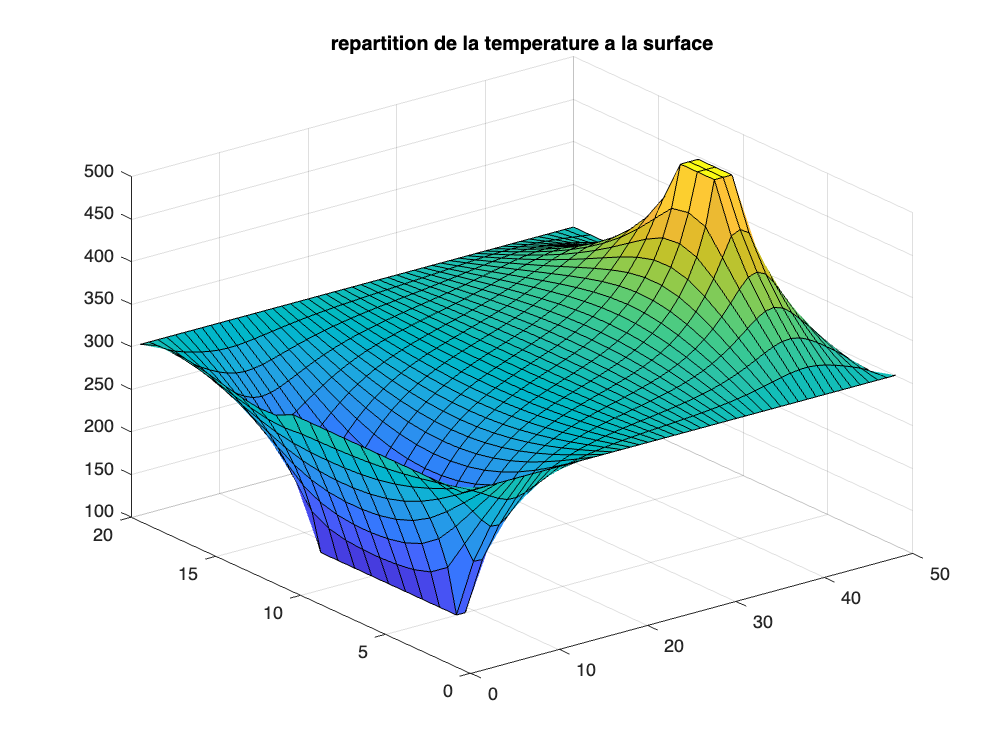

X = Gauss(A, B, 0.01);
X = reshape(X,[50,20])'; % reshape back en matrice
figure(1)
surf(X)
title('repartition de la temperature a la surface')

#### Propagation de la temperature

Désormais, la répartition des temperatures depend du temps.

**Evolution libre :**

On part de la solution de la partie d'avant et on simule son évolution dans le temps pour atteindre l'équilibre.

Cet equilibre est stable, la temperature d'équilibre est de 292.3587 °C, et est atteinte après 3000 unités de temps (ca correspond à 30 sec sans les pauses, et environ à 2,2 min avec).

temps = 3000;
evolLibre(A, B, temps);

**Chauffage externe :**

On part d'une plaque métallique dont la surface est entièrement à 0 °C. A chaque pas de temps, on chauffe la plaque à partir des neuf points rouges qui sont à 500 °C et qui sont remis à 500 °C *à chaque pas de temps*. On chauffera jusqu'à atteindre un état d'équilibre (ou presque).

Cet equilibre est stable, la temperature d'équilibre est de 499.99 °C à 0.01 près (la temperature de chauffe sans surprise) et est atteinte après 5500 unités de temps (ca correspond à 47 sec sans les pauses soit 4 min avec - et à 4500 unités de temps pour t° ≈ 499.95 °C).

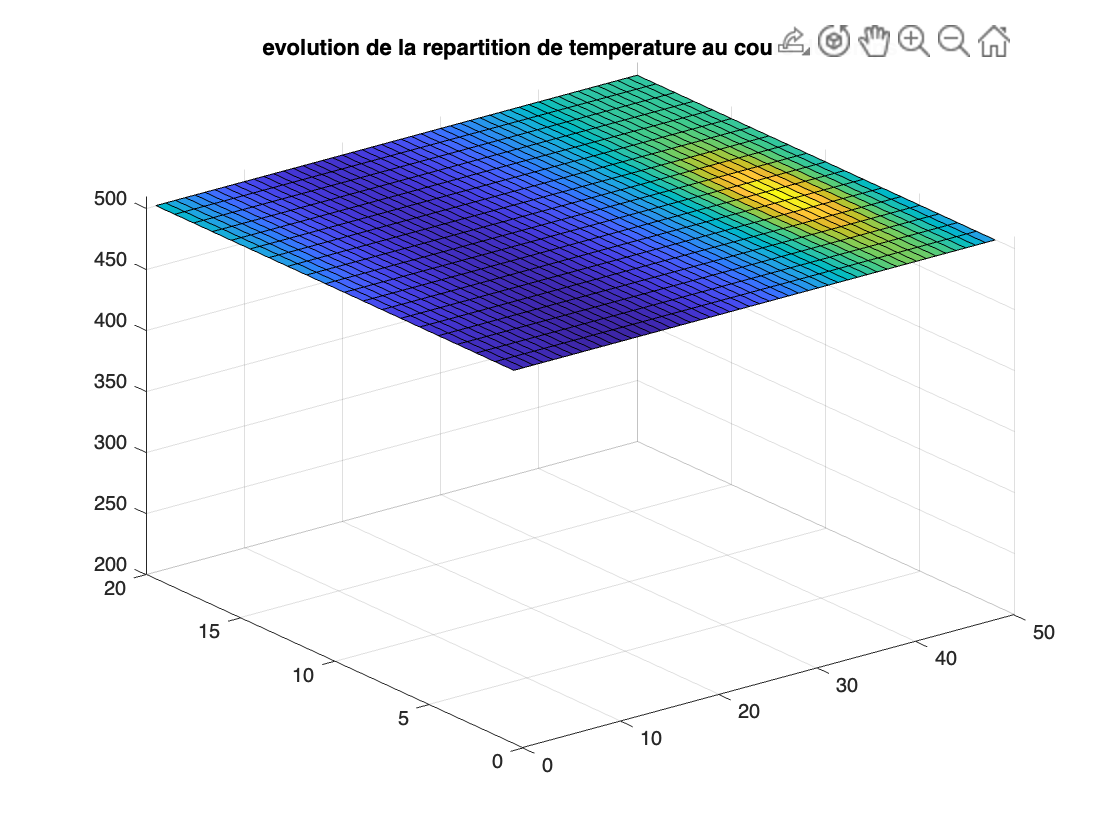

la temperature a l equilibre est de 499.9927


temps = 5500;
chauffage(A, temps);